**Traslación en el Tiempo**

%-----APLICANDO LAS PROPIEDADES 
clear all;
close all;
clc;

%-----Traslación en el tiempo
Fs=100;
A=4;
t=-1+A:1/Fs:2+A;
L=3000;         %Longitud de la señal 
s=((4/3)*(t-A)-2/3) %Traslación en el t

s =    -2.0000   -1.9867   -1.9733   -1.9600   -1.9467   -1.9333   -1.9200   -1.9067   -1.8933   -1.8800   -1.8667   -1.8533   -1.8400   -1.8267   -1.8133   -1.8000   -1.7867   -1.7733   -1.7600   -1.7467   -1.7333   -1.7200   -1.7067   -1.6933   -1.6800   -1.6667   -1.6533   -1.6400   -1.6267   -1.6133   -1.6000   -1.5867   -1.5733   -1.5600   -1.5467   -1.5333   -1.5200   -1.5067   -1.4933   -1.4800   -1.4667   -1.4533   -1.4400   -1.4267   -1.4133   -1.4000   -1.3867   -1.3733   -1.3600   -1.3467


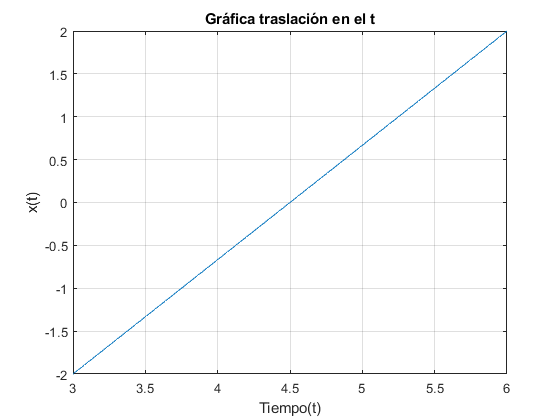

Y=fft(s,L);     %Aplicando transformada rápida

plot(t,s);
title('Gráfica traslación en el t')
xlabel('Tiempo(t)');
ylabel('x(t)');
grid on

figure   

P=abs(Y/Fs);
f=linspace(0,Fs,numel(P));

plot(f,P)
axis ([0 5 0 3])
title('Gráfica transformada rápida')
xlabel('Frecuencia(rad/s)')
ylabel('|X(f)|')
grid on

syms t f;       %Variables simbólicas
e=3;
xtt=((4/3)*(t-e)-2/3);  %
ytt=int(xtt*exp(-1i*2*pi*f*t),t,-1+e,2+e) %Transformada de Fourier teórica

$$ytt = \frac{{\mathrm{e}}^{-10\,\pi \,f\,\mathrm{i}}\,\left(1-{\mathrm{e}}^{6\,\pi \,f\,\mathrm{i}}+3\,\pi \,f\,\mathrm{i}+3\,\pi \,f\,{\mathrm{e}}^{6\,\pi \,f\,\mathrm{i}}\,\mathrm{i}\right)}{3\,f^{2}\,\pi^{2}}$$

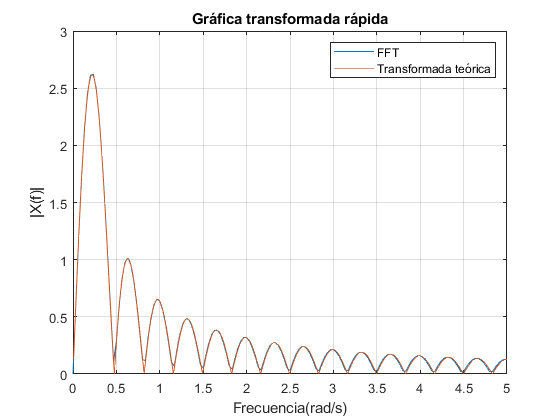

hold on         %sobreposición
fplot(f,abs(ytt),[0 5])
legend('FFT','Transformada teórica')
grid on

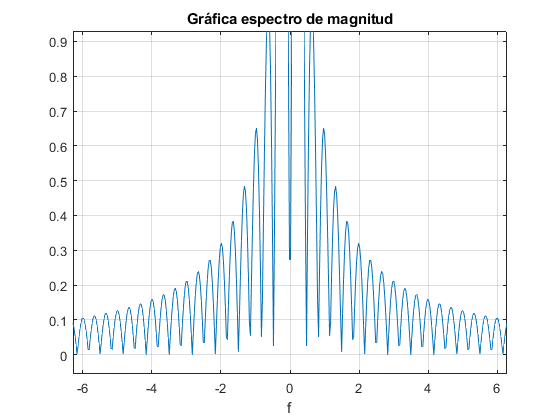

figure


%-----Gráfica espectro de magnitud
ezplot(abs(ytt));
title('Gráfica espectro de magnitud')
grid on